CAPTURA DE SONIDO

CapturaAudio = audiorecorder (8000,8,1)

CapturaAudio =   audiorecorder with properties:

       SampleRate: 8000
    BitsPerSample: 8
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 0
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audiorecorder'


Con esto creas un objeto que se utiliza para capturar sonido. 

8000 = Tasa de muestreo

8 = Bits/muestra

1 = nº de canales

disp ('Empieza a hablar.')

Empieza a hablar.


recordblocking (CapturaAudio,4)
disp ('Fin de la grabación')

Fin de la grabación


Con esto grabamos un audio de 4s en el objeto que creamos antes.

play (CapturaAudio);
voz = getaudiodata (CapturaAudio)

voz =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Con getaudiodata conviertes el audio grabado en CapturaAudio en un vector.

whos

  Name                      Size               Bytes  Class            Attributes

  CapturaAudio              1x1                    8  audiorecorder              
  ans                       1x1                    8  audioplayer                
  audio_l              125000x2              2000000  double                     
  audio_r              125000x2              2000000  double                     
  f_guitarra                1x1                    8  double                     
  fase                      1x1                    8  double                     
  fs                        1x1                    8  double                     
  indice                    1x1                    8  double                     
  n                         1x100                800  double                     
  v_guitarra           125000x2              2000000  double                     
  valor_max                 1x1                    8  double                     
  voz          

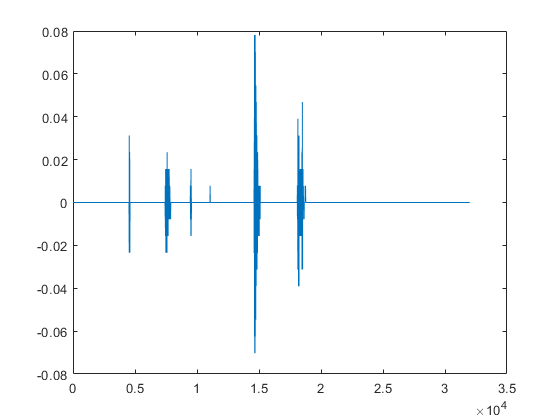

plot (voz)

whos te enseña las variable con su tamaño, el tipo de variable y mas datos.

plot representa el vector voz en una grafica.

voz_2 = voz (1: 20000);

Con esto coges los 20.000 primeros valores del vector voz. Esto lo hacemos porque la segunda parte del mensaje está vacío o es ruido.

fs = 8000;
voz_3 = voz (end:-1:1)

voz_3 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


y = audioplayer (voz_3,fs)

y =   audioplayer with properties:

       SampleRate: 8000
    BitsPerSample: 16
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 32000
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


play (y);

El segundo comando le da la vuelta al vector y el tercero crea una variable y de audio que tiene como datos los del vector y una frecuencia de muestreo dada por fs (8000).

voz_4 = voz (1:2:end)

voz_4 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


y = audioplayer (voz_4,fs)

y =   audioplayer with properties:

       SampleRate: 8000
    BitsPerSample: 16
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 16000
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


play (y)

Esto hace que la grabación vaya el doble de rápido, ya que solo coge la mitad (pares o impares) de los valores del vector voz.

[valor_max, indice] = max(abs(voz))

valor_max = 0.0781

indice = 14642

voz_normalizada = voz / valor_max

voz_normalizada =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


sound (voz_normalizada, fs)
soundsc(voz_normalizada*30, fs)
sound (voz_normalizada*30, fs)

Normaliza la voz. El soundsc la reescala pero el sound no, así que suena la voz normalizada.

ALMACENAMIENTO DEL WORKSPACE

save datos_pr1 fs voz voz_3

El primer argumento es el nombre del fichero .mat en el que se guardan las variables que tu elijas (los siguientes argumentos).

load datos_pr1 fs voz voz_3

Funciona igual que el save, pero cargando datos.

audiowrite ('martes.wav', voz_2, 8000)

Crea un fichero .wav (en este caso) en el que guarda el vector voz_2 y con la frecuencia de muestreo 8.000 (para cuando se reproduzca saber a que tasa de muestreo tiene que hacerlo).

MANEJO DE MATRICES Y VECTORES

[v_guitarra, f_guitarra] = audioread ('guitarra.wav')

v_guitarra =    -0.0565   -0.0399
   -0.0665   -0.0248
   -0.0697   -0.0050
   -0.0661    0.0083
   -0.0558    0.0103
   -0.0398    0.0020
   -0.0200   -0.0127
    0.0010   -0.0284
    0.0201   -0.0394
    0.0344   -0.0440


f_guitarra = 44100

Lee el vector del archivo y lo mete en v_guitarra y su frecuencia de muestreo en f_guitarra.

audio_r = v_guitarra(:,1)

audio_r =    -0.0565
   -0.0665
   -0.0697
   -0.0661
   -0.0558
   -0.0398
   -0.0200
    0.0010
    0.0201
    0.0344


audio_l = v_guitarra(:,2)

audio_l =    -0.0399
   -0.0248
   -0.0050
    0.0083
    0.0103
    0.0020
   -0.0127
   -0.0284
   -0.0394
   -0.0440


Con esto divides el estereo en izquierda y derecha.

sound (audio_l, f_guitarra)
sound (audio_r, f_guitarra)

La diferencia es que ahora cada uno de los lados suena en mono.

x = zeros (125000, 1);
audio_r = horzcat (x, audio_r)

audio_r =          0   -0.0565
         0   -0.0665
         0   -0.0697
         0   -0.0661
         0   -0.0558
         0   -0.0398
         0   -0.0200
         0    0.0010
         0    0.0201
         0    0.0344


audio_l = horzcat (audio_l, x)

audio_l =    -0.0399         0
   -0.0248         0
   -0.0050         0
    0.0083         0
    0.0103         0
    0.0020         0
   -0.0127         0
   -0.0284         0
   -0.0394         0
   -0.0440         0


sound (audio_l, f_guitarra)
sound (audio_r, f_guitarra)

Con esto le metes una fila de ceros al lado que no tiene audio para que sigas siendo estereo (en este caso solo suena cada pista por un lado).

SCRIPTS *.m Y GRÁFICASs

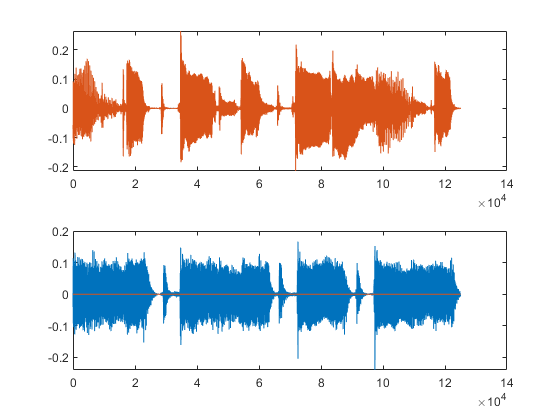

figure (1)
subplot (2,1,1)
plot(audio_r)
subplot (2,1,2)
plot (audio_l)

El subplot divide la pestaña de la gráfica en un "matriz" (2x1 en este caso) y el tercer número indica a que casilla de la división afecta el plot siguiente, así que podemos meter varias funciones en la misma ventana.

[https://www.youtube.com/watch?v=ccHyAraGopE](https://www.youtube.com/watch?v=ccHyAraGopE) (video explicando el subplot)

FÓRMULA DE EULER

n = 0:99

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


w0 = pi/3

w0 = 1.0472

fase = pi/5

fase = 0.6283

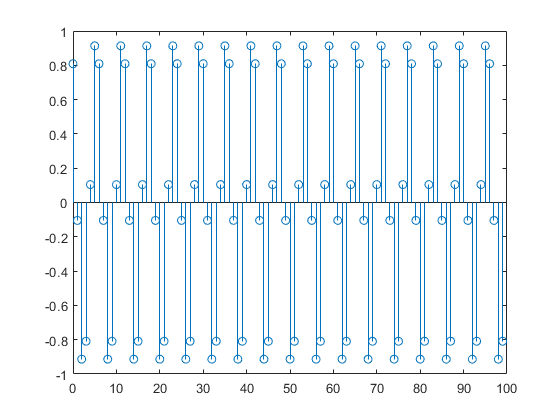

x = cos (w0 * n + fase);
figure (2)
stem (n, x)

El stem Hace la gráfica sin completarla (poniendo solo los puntos que tu le pones).

x1 = exp(1j * (w0 * n + fase))
x2 = conj (x1)
xcos = (x1 + x2) / 2
hold on
stem(n, xcos, 'r')

El hold on te deja seguir metiendo cosas en la misma gráfica.

figure (3)
stem (n, x)
x = sin(w0 * n + fase);
stem(n, x, 'g')

OPERACIONES ELEMENTO A ELEMENTO

w0 = pi/3;
w1 = pi/6;
x1 = cos(w0 * n);
x2 = cos(w1 * n);
stem (n, x1)
hold on;
stem (n, x2, 'g')

La primera tiene la mital de periodo que la segunda (12 y 6), ya que tiene la mitad de frecuencia.

figure (4)
y = x1 .* x2;
stem (n, y, 'p')

Hace una onda de frecuencia 12 (ojo, la forma de la onda es rara)

y1 = x1 * x2'

Da el producto escalar de los dos vectores.

y2 = x1' * x2

Da la matriz 100x100 del producto de los vectores.

ESCUCHAR TONOS Y ALIASING

w0 = 2 * pi ./ [40 20 10 5 4 2]
fs = 8000
wd0 = w0 ./ fs;

Te dan una serie de frecuencias y con eso calculas la ______ digital

n = 0:9999;
fs = 8000;
for i = 1 : length (w0)
    x = cos (w0 (i) * n);
    soundsc (x, fs)
    pause
end

Reproduce todas las frecuencias de w0 a la frecuencia fs (tienes que darle al enter cada vez que quieras oir uno)

w1 = 2 * pi ./ [40 20 10 5 4 2] + 2 * pi
for i=1: length(w1)
    x = cos(w1(i)*n);
    soundsc(x,fs)
    pause
end

Ahora suena la inversa de las anteriores (desplazado medio periodo). Es lo que hace que ocurra lo de que en estéreo suene y en mono no